# Interval Bisection 1D

function [n,as,bs,cs,fas,fbs,fcs] = interval_bisection(a0,c0,func,N,tol)
    n = 1;
    as = zeros(N+1);
    bs = zeros(N+1);
    cs = zeros(N+1);
    as(1) = a0;
    bs(1) = (a0+c0)/2;
    cs(1) = c0;

    fas = zeros(N+1);
    fbs = zeros(N+1);
    fcs = zeros(N+1);
    fas(1) = func(as(1));
    fbs(1) = func(bs(1));
    fcs(1) = func(cs(1));

    while n<N
        if fas(n)*fbs(n)<0
            as(n+1) = as(n);
            cs(n+1) = bs(n);
            fas(n+1) = fas(n);
            fcs(n+1) = fbs(n);
        else
            as(n+1) = bs(n);
            cs(n+1) = cs(n);
            fas(n+1) = fbs(n);
            fcs(n+1) = fcs(n);
        end

        bs(n+1) = (as(n+1)+cs(n+1))/2;
        fbs(n+1) = func(bs(n+1));

        n=n+1;

        if cs(n)-as(n) < tol*(c0-a0)
            break;
        end
    end

    as = as(1:n);
    bs = bs(1:n);
    cs = cs(1:n);
    fas = fas(1:n);
    fbs = fbs(1:n);
    fcs = fcs(1:n);
end

## Plotting function

function plot_function(ax,f,xmin,xmax)
    plot(ax,[xmin xmax],[0 0],'-k');
    range = xmax-xmin;
    density = 100;
    x = linspace(xmin,xmax,range*density);
    y = f(x);
    plot(ax,x,y,'-b');
end

function plot_step(ax,a,b,c,fa,fb,fc)
    plot(ax,[a a],[0 fa],"-k");
    plot(ax,[c c],[0 fc],"-k");
    scatter(ax,[a c],[fa fc],".b");
    scatter(ax,b,fb,".r");
end

function plot_all(ax,f,xmin,xmax,a,b,c,fa,fb,fc)
    plot_function(ax,f,xmin,xmax);
    plot_step(ax,a,b,c,fa,fb,fc);
end

## Driver

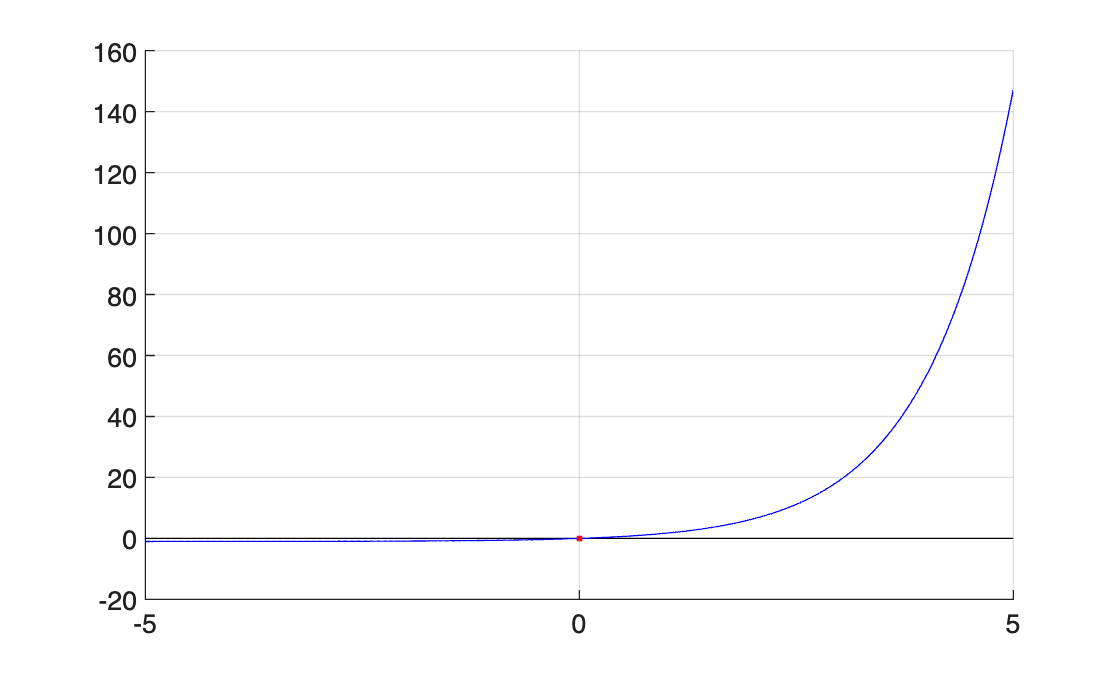

f = @(x) exp(x)-1;

xmin = -5;
xmax = 5;


N = 1000;
tol = 3e-15;

a0 = -3.5;
c0 = 1.5;

[n,as,bs,cs,fas,fbs,fcs] = interval_bisection(a0,c0,f,N,tol);


ax = gca;
cla(ax);
hold(ax,'on');

step = 20;

plot_all(ax,f,xmin,xmax,as(step+1),bs(step+1),cs(step+1),fas(step+1),fbs(step+1),fcs(step+1));

hold(ax,'off');
grid on;


n

n = 50

as(step+1)

ans = -9.5367e-07

bs(step+1)

ans = 1.4305e-06

cs(step+1)

ans = 3.8147e-06